if ~exist('data/chap06', 'dir')
    gunzip('https://github.com/sp-au-mu-nl/SpeechComm/raw/refs/heads/main/data/chap06.zip','data')
    unzip('data/chap06.zip', 'data/chap06/')
end

プログラム 6.2

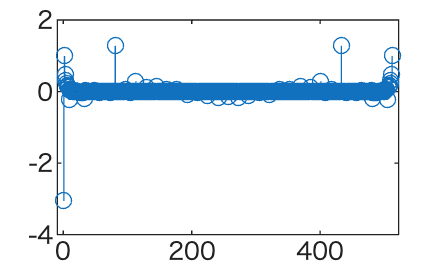

[s, sr] = audioread('data/chap06/chap06_synth_vowel.wav');
nFFT = 512;
S = fft(s(1:nFFT).*hann(nFFT));
LS = log(abs(S));
c = ifft(LS);
stem(c)

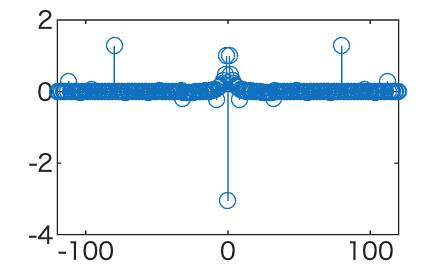

x = (0:length(c)-1)-length(c)/2;
stem(x, fftshift(c));
xlim([-120 120])

cShift = fftshift(c);
cShift((256+1)+(-2:2))

ans =     0.4903
    0.9969
   -3.0562
    0.9969
    0.4903


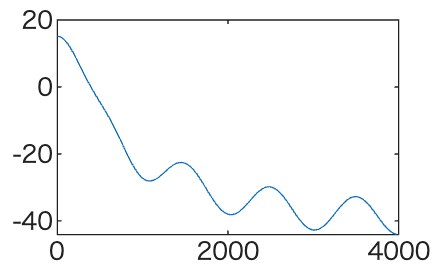

order = 14;
cGVLow = c;
cGVLow(order+2:end-order) = 0;
GVLow = real(fft(cGVLow));
f = linspace(0, sr/2, nFFT/2+1);
plot(f, 20*GVLow(1:nFFT/2+1)/log(10))

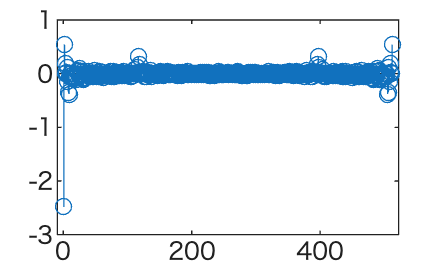

[ySa, sr] = audioread('data/chap06/sa48k.wav');
ySa = filter([1 -.97], 1, resample(ySa, 16000, sr));
sr = 16000;
nFFT = 512;
yA = ySa(7000+(1:nFFT)).*hann(nFFT);
SA = fft(yA);
cA =cepstrum(SA);
cALow = liftering(cA, 20);
stem(cA)

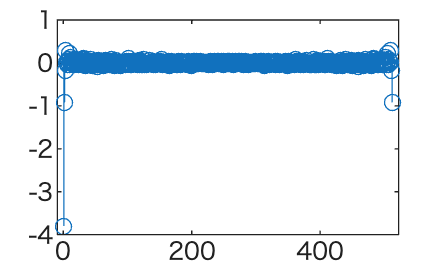

SS = fft(ySa(2500+(1:nFFT)).*hann(nFFT));
cS = cepstrum(SS);
cSLow = liftering(cS, 20);
stem(cS)

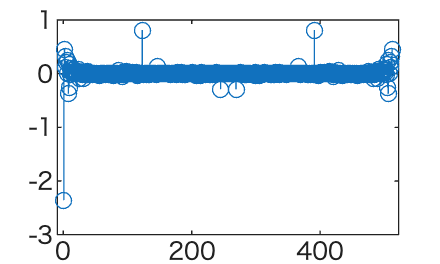

yA131 = twoTubeSynth(sr, 131, 0.17, 340, 0.7, 1.0, 1/7, 1);
yA131 = filter([1 -.97], 1, yA131);
nFFT = 512;
SA131 = fft(yA131(1:nFFT).*hann(nFFT));
cA131 = cepstrum(SA131);
cA131Low = liftering(cA131, 20);
stem(cA131)

norm(cALow-cSLow)^2

ans = 7.4777

norm(cALow-cA131Low)^2

ans = 0.7220

norm(cSLow-cA131Low)^2

ans = 7.6302

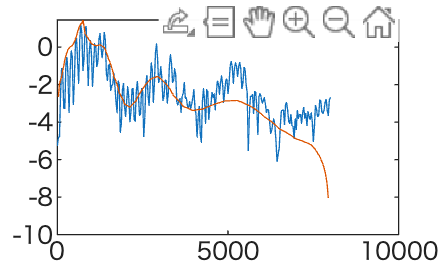

[ySa, sr] = audioread('data/chap06/sa48k.wav');
ySa = resample(ySa, 16000, sr);
sr = 16000;
ySa = filter([1 -.97], 1, ySa);
nFFT = 512;
yA = ySa(7000+(1:nFFT)).*hann(nFFT);
SA = fft(yA);
f = 0:sr/nFFT:sr/2;
nBank = 40;
[melFilterBank, fc] = melbank();
melSA = log(melFilterBank*abs(SA(1:length(melFilterBank))));
order = 13;
mfccSA = dct(melSA);
mfccSA(order:end) = 0;
mfccSA(1) = 0;
plot(f, log(abs(SA(1:length(melFilterBank))))); hold on
plot(f, log(sum(exp(idct(mfccSA)).*melFilterBank,1))); hold off

function LS = cepstrum(S)
LS = ifft(log(abs(S)));
end

function out_ceps = liftering(in_ceps, order)
if nargin < 2
    order = 14;
end
out_ceps = in_ceps;
out_ceps(order+2:end-order) = 0;
end

function mel = hz2mel(freq)
mel = 1127 * log(1+freq/700);
end

function freq = mel2hz(mel)
freq = (exp(mel/1127)-1)*700;
end

function g = glottalpulse(fs, T1, T2)
if nargin < 3
    T1 = 0.004;
    T2 = 0.002;
end
t1=0:1/fs:T1;
g1=0.5*(1-cos(2*pi*t1/2/T1));
t2=T1+1/fs:1/fs:T1+T2;
g2=cos(2*pi*(t2-T1)/4/T2);
g=[g1 g2];
end

function H = freqz_two_tube(f, rL, rG, r1, L, c, L1L2)
H = 0.5*(1+rG)*(1+rL)*(1+r1) * exp(-2j*pi*f*L/c) ... 
    ./ (1+r1*rG*exp(-2j*pi*f*2*L1L2/(L1L2+1)*L/c)... 
         + r1*rL*exp(-2j*pi*f*2/(1+L1L2)*L/c)+rL*rG*exp(-2j*pi*f*2*L/c));
end

function vowel = twoTubeSynth(fs, fo, L, c, rL, rG, a1a2, L1L2)
r1 = (1-a1a2)/(1+a1a2);
g = glottalpulse(fs);
imp_len = 1/fo;
nimp = round(imp_len*fs/2)*2;
imp(1) = 1;
imp(nimp) = 0;
x_imp = repmat(imp, 1, nimp);
y_glottal = filter(g, 1, x_imp);
f = 0:length(y_glottal)/2-1;
V = freqz_two_tube(f, rL, rG, r1, L, c, L1L2);
S_glottal = fft(y_glottal);
vowel = real(ifft([V conj(fliplr(V))].*S_glottal))';
end

function [melFilterBank, fc] = melbank(sr, nFFT, nBank, lower, upper)
if nargin < 4
    lower = 0;
    upper = 8000;
end
if nargin < 3
    nBank = 40;
end
if nargin < 2
    nFFT = 512;
end
if nargin < 1
    sr = 16000;
end
frequency = linspace(0,sr/2,nFFT/2+1);
melFilterBank = zeros(nBank, nFFT/2+1);
nMelWindowLow = round(400/3/(sr/nFFT));
if mod(nMelWindowLow, 2) ~= 0
    nMelWindowLow = nMelWindowLow + 1; % Ensure it's even
end
windowMelIncLow = linspace(0, 1, nMelWindowLow/2+1);
windowMelDecLow = linspace(1, 0, nMelWindowLow/2+1);
windowMelTriLow = [windowMelIncLow windowMelDecLow(2:end)];
windowMelTriLowNormalized = windowMelTriLow/sum(windowMelTriLow);
centerLow = nMelWindowLow/2:nMelWindowLow/2:12*nMelWindowLow/2;
for iCenterLow = 1:length(centerLow)
    start = centerLow(iCenterLow)-nMelWindowLow/2;
    melFilterBank(iCenterLow, start+(1:nMelWindowLow+1)) = ...
        windowMelTriLowNormalized;
end

upperMel = hz2mel(upper);
lowerMel = hz2mel(frequency(centerLow(end)+1));
stepMel = (upperMel-lowerMel)/(nBank+1-length(centerLow));
center = round(mel2hz(lowerMel:stepMel:upperMel)/(sr/2)*(nFFT/2));
for iCenter = 1:length(center)-2
    t0 = center(iCenter); t1 = center(iCenter+1); t2 = center(iCenter+2);
    iCurrent = iCenterLow+iCenter;
    melFilterBank(iCurrent, t0:t1) = linspace(0, 1, t1-t0+1);
    melFilterBank(iCurrent, t1:t2) = linspace(1, 0, t2-t1+1);
    melFilterBank(iCurrent, :) = melFilterBank(iCurrent, :) / ...
        sum(melFilterBank(iCurrent, :));
end

fc1 = mel2hz(frequency(centerLow));
fc2 = frequency(center(1:end-1));
fc = [fc1 fc2];
end